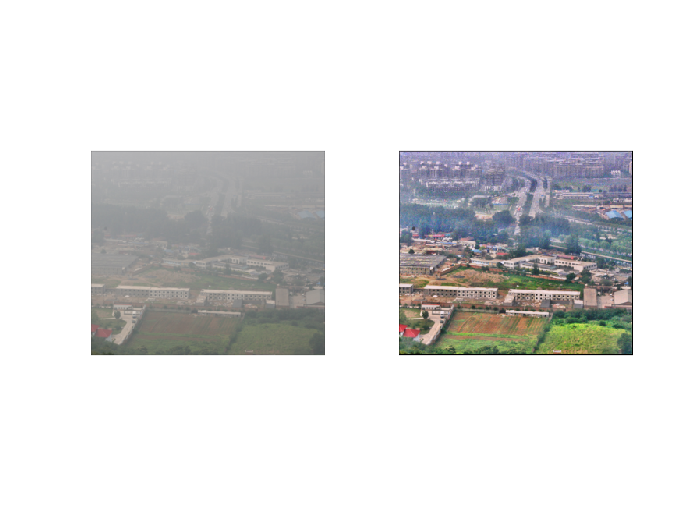

clear;clf;
input=imread('Homework1_images/q1/Ex_ColorEnhance.png');
subplot(1,2,1);
title('Input Image');
imshow(input);

output = F_CLAHE_simple(input,0.3);
colorBalance = F_Wbalance(output);
subplot(1,2,2);
title('Output Image');
imshow(uint8(colorBalance));

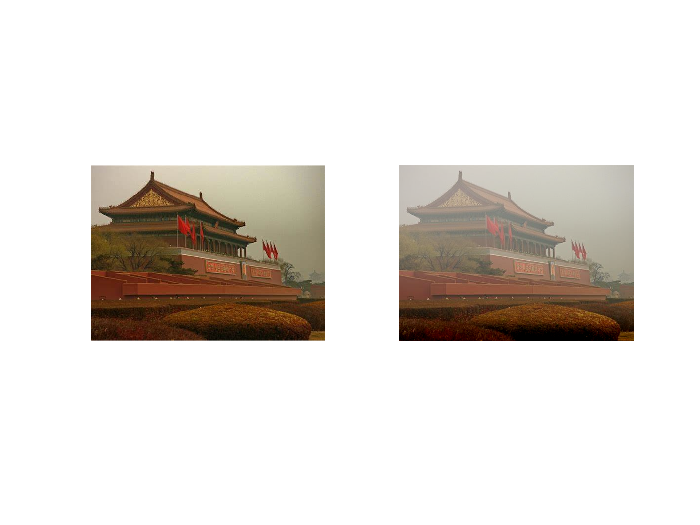

clear;clf;
inputGray=imread('Homework1_images/q1/Tam_clear.jpg');
subplot(1,2,1);
title('Input Image');
imshow(inputGray);

A = 0.8;
m = 50;
beta = 0.08;
grayT = F_Fogtest(inputGray,m,A,beta);
subplot(1,2,2);
title('Output Image');
imshow(grayT);

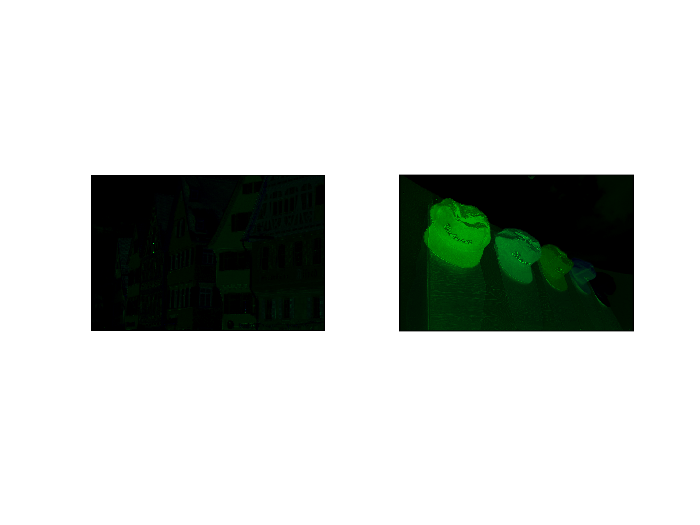

clear;clf;
source = imread('Homework1_images/q3/houses.bmp');
target = imread('Homework1_images/q3/hats.bmp');

source_lab = F_rgb2lab(source);
subplot(1,2,1);
imshow(source_lab);

target_lab = F_rgb2lab(target);
subplot(1,2,2);
imshow(target_lab);

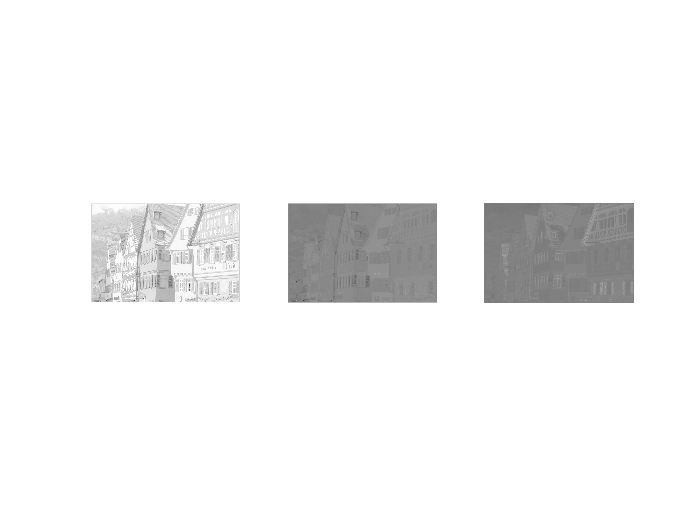

clf;
subplot(1,3,1);
imshow(source_lab(:,:,1),[]);
subplot(1,3,2);
imshow(source_lab(:,:,2),[]);
subplot(1,3,3);
imshow(source_lab(:,:,3),[]);

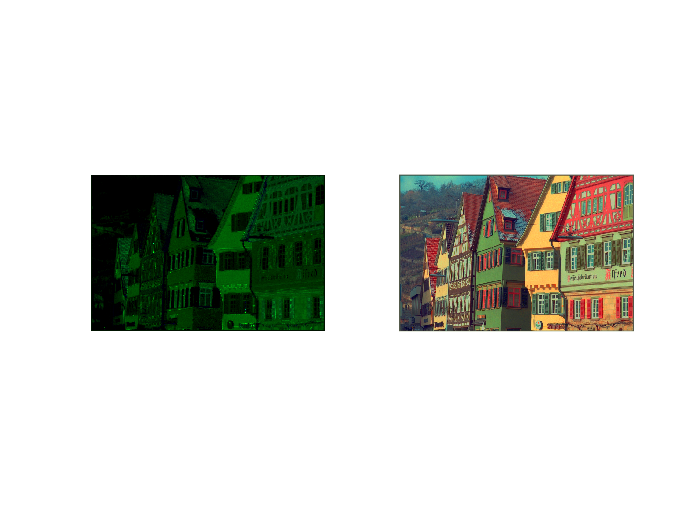

clf;
output_correctionLab = F_ColorCorrection(source_lab, target_lab);
subplot(1,2,1);
imshow(output_correctionLab);
output_transform = F_lab2rgb(output_correctionLab);
subplot(1,2,2);
imshow(output_transform);

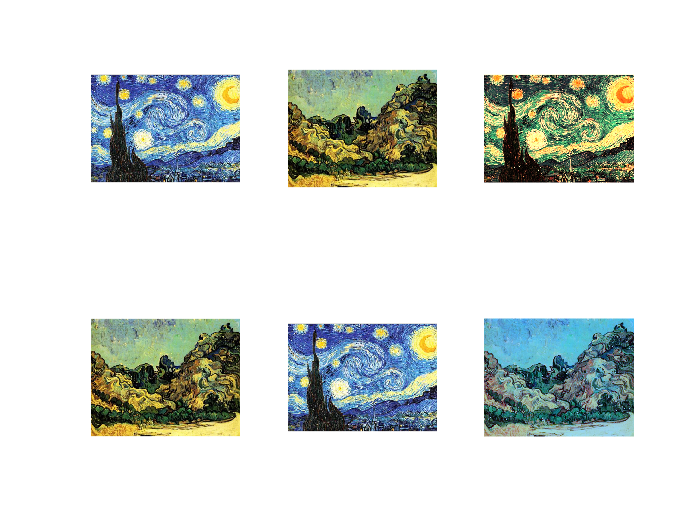

clf;
input_mount = imread('Homework1_images/q3/Mountains.png');
subplot(2,3,4);
imshow(input_mount);
subplot(2,3,2);
imshow(input_mount);
input_night = imread('Homework1_images/q3/Starry_night.png');
subplot(2,3,1);
imshow(input_night);
subplot(2,3,5);
imshow(input_night);

output_mount = F_rgb2lab(input_mount);
output_night = F_rgb2lab(input_night);

output_mount2night = F_ColorCorrection(output_night, output_mount);
output_mount2night = F_lab2rgb(output_mount2night);
subplot(2,3,3);
imshow(output_mount2night);

output_night2mount = F_ColorCorrection(output_mount, output_night);
output_night2mount = F_lab2rgb(output_night2mount);
subplot(2,3,6);
imshow(output_night2mount);

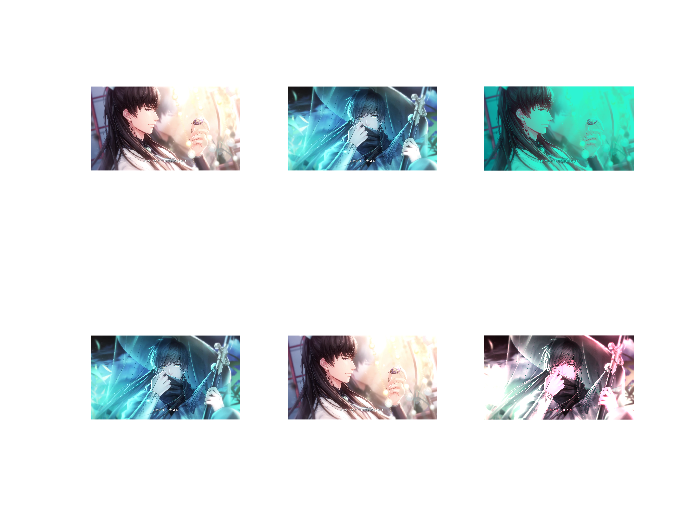

clf;clear;
input_mount = imread('Homework1_images/q3/Bai.png');
subplot(2,3,4);
imshow(input_mount);
subplot(2,3,2);
imshow(input_mount);
input_night = imread('Homework1_images/q3/Xu.png');
subplot(2,3,1);
imshow(input_night);
subplot(2,3,5);
imshow(input_night);

output_mount = F_rgb2lab(input_mount);
output_night = F_rgb2lab(input_night);

output_mount2night = F_ColorCorrection(output_night, output_mount);
output_mount2night = F_lab2rgb(output_mount2night);
subplot(2,3,3);
imshow(output_mount2night);

output_night2mount = F_ColorCorrection(output_mount, output_night);
output_night2mount = F_lab2rgb(output_night2mount);
subplot(2,3,6);
imshow(output_night2mount);

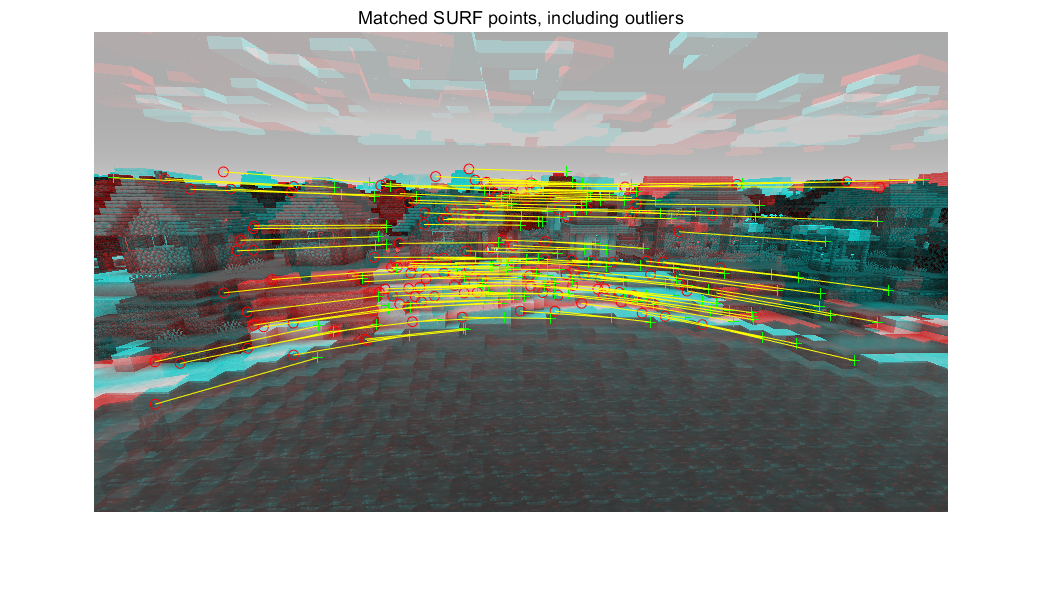

original = imread('Homework1_images/q2/mc1/1.png'); 
distorted = imread('Homework1_images/q2/mc1/2.png'); 

original = rgb2gray(original);
distorted = rgb2gray(distorted);

[ori_row, ori_col] = size(original);
[dis_row, dis_col] = size(distorted);

ptsOriginal = detectSURFFeatures(original); 
ptsDistorted = detectSURFFeatures(distorted); 

% Generate descriptive features
[featuresOriginal,validPtsOriginal] = extractFeatures(original,ptsOriginal); 
[featuresDistorted,validPtsDistorted] = extractFeatures(distorted,ptsDistorted);
% Descriptive feature matching
% TODO: find the min eucidian distance for good match (1st near and 2nd
% near)
index_pairs = matchFeatures(featuresOriginal,featuresDistorted,'Method','Approximate','Unique',true); 


% Matched key points
matchedPtsOriginal = validPtsOriginal(index_pairs(:,1)); 
matchedPtsDistorted = validPtsDistorted(index_pairs(:,2)); 

%Show matching points
figure;
showMatchedFeatures(original,distorted,matchedPtsOriginal,matchedPtsDistorted);
title('Matched SURF points, including outliers'); 

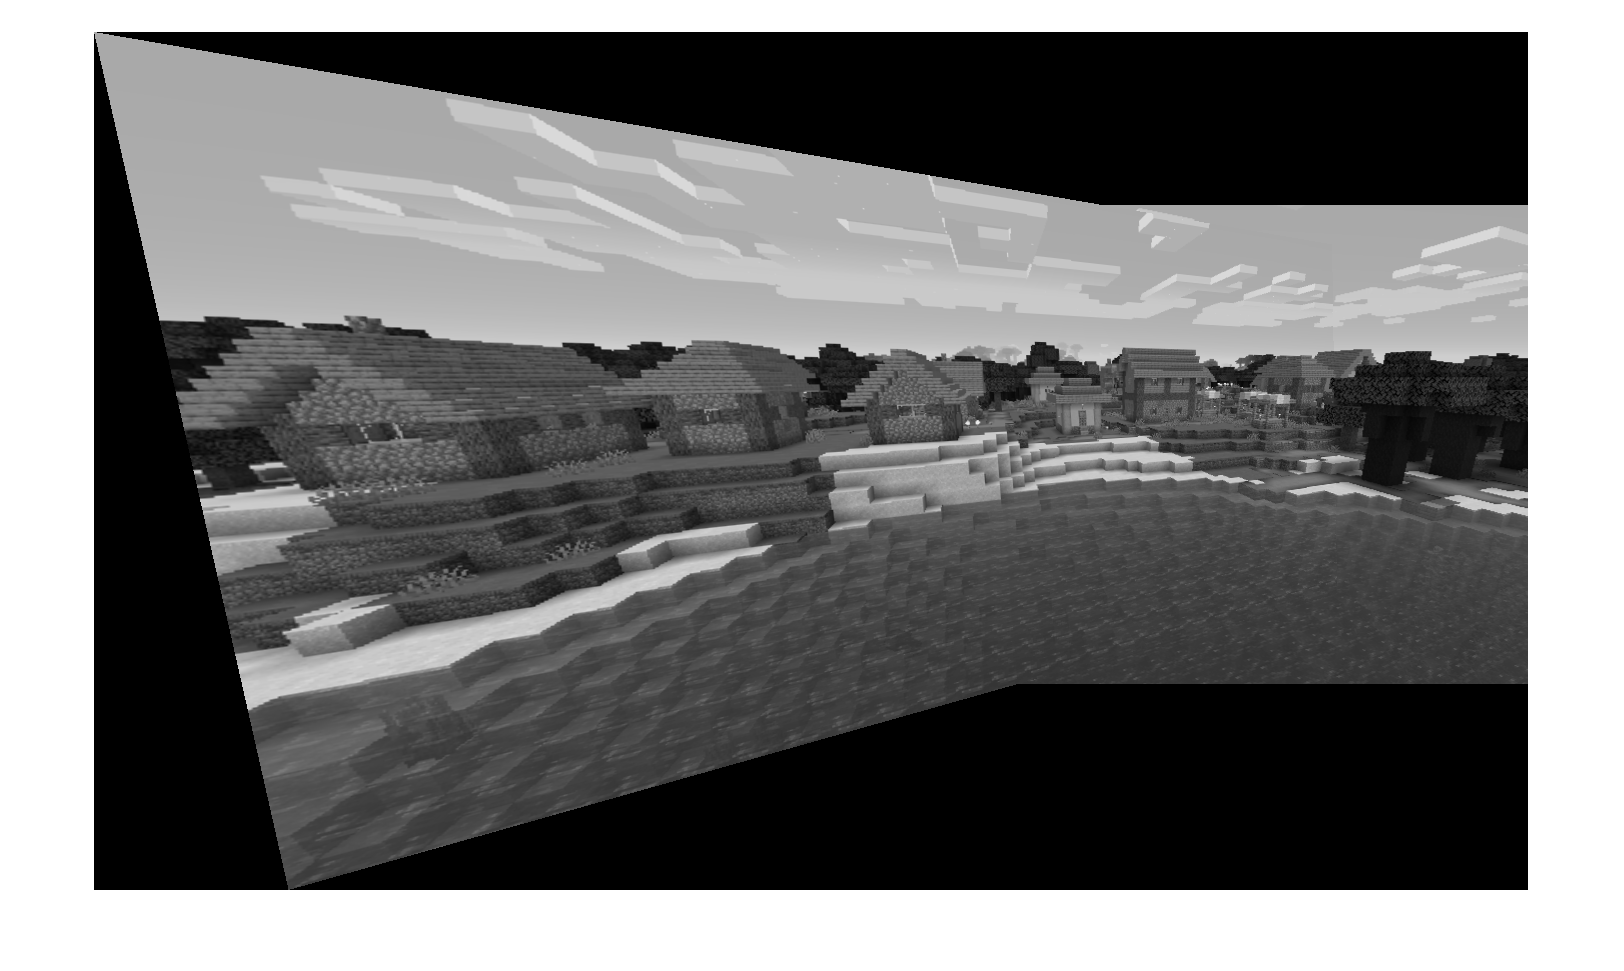


%Estimate geographic transform matrix
tform = estimateGeometricTransform(matchedPtsDistorted,matchedPtsOriginal,'projective'); 

[xlim_ori,ylim_ori]=outputLimits(projective2d(eye(3)),[1 ori_col],[1 ori_row]);
[xlim_des,ylim_des]=outputLimits(tform,[1 ori_col],[1 ori_row]);
maxImgSize = max([ori_row,ori_col;dis_row,dis_col]);

xlim = [xlim_ori;xlim_des];
ylim = [ylim_ori;ylim_des];
% Find the minimum and maximum output limits. 
xMin = min([1; xlim(:)]);
xMax = max([maxImgSize(2); xlim(:)]);
yMin = min([1; ylim(:)]);
yMax = max([maxImgSize(1); ylim(:)]);
% Width and height of panorama.
width  = round(xMax - xMin);
height = round(yMax - yMin);
% Initialize the "empty" panorama.
panorama = zeros(height,width);

blender = vision.AlphaBlender('Operation', 'Binary mask', ...
    'MaskSource', 'Input port'); 
%Compute the estimated registration result
xLimits = [xMin xMax];
yLimits = [yMin yMax];
panoramaView = imref2d([height width], xLimits, yLimits);

warpedImage = imwarp(original,projective2d(eye(3)),'OutputView',panoramaView);
mask = imwarp(true(size(original,1),size(original,2)),projective2d(eye(3)) , 'OutputView', panoramaView);
panorama = step(blender, panorama, im2double(warpedImage), mask);

warpedImage = imwarp(distorted,tform,'OutputView',panoramaView);
mask = imwarp(true(size(distorted,1),size(distorted,2)),tform , 'OutputView', panoramaView);
panorama = step(blender, panorama, im2double(warpedImage), mask);

figure; 
imshow(panorama); 